# Lesson 3

Written by Brenda So and Cory Nezin, modified by Guy Bar Yosef.

# Objective

After this class, you should be able to:

- Understand how to plot graphs and display tables

- Know how to write anonymous and normal functions

- Understand why for loops can be inefficient

# Plotting

We are going to go through several plotting schemes and explore how you can customize plotting. We will go through 2D plotting, surface plotting, subplot, stem plot, and 3D plotting.

**NOTE: **There are many more plotting features, we urge you to explore the documentation for whatever graph/plot fits your data best. 

# Plotting in 2D

2D plots are very straightforward, it's what you expect from a textbook or when you are graphing.

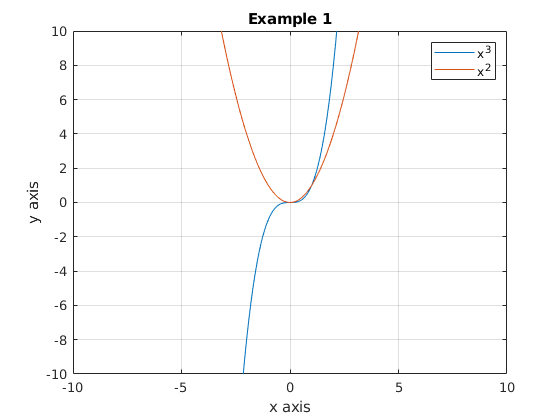

% Example 1: Plotting y=x^3

x = -10:0.1:10;
y = x.^3;
plot(x,y,'DisplayName','x^3');              % plotting line graph
xlabel('x axis');
ylabel('y axis');
title('Example 1');
grid on;
axis([-10 10 -10 10]);

hold on;                % plotting more than 1 plot on 1 figure rather than overwriting

y2 = x.^2;
plot(x, y2, 'DisplayName','x^2');
legend('show');

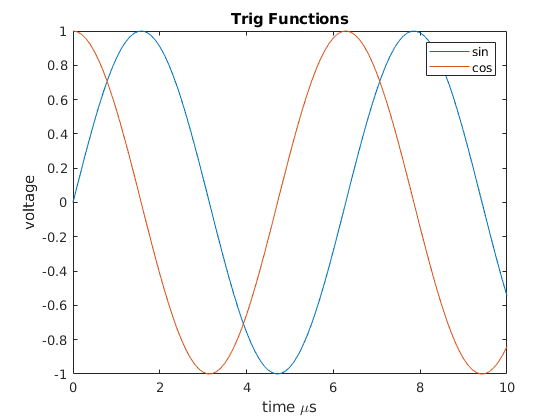

% Example 2: Plotting sine and cosine

t = 0:.1:10;
d1 = sin(t);
d2 = cos(t);

figure 
plot(t,[d1.', d2.']) % plot(t,d1,t,d2)

title('Trig Functions')
xlabel('time \mus') % \mus is a special symbol. Other examples include: \beta, \pi, \leq, \infty 
ylabel('voltage')
legend('sin','cos')

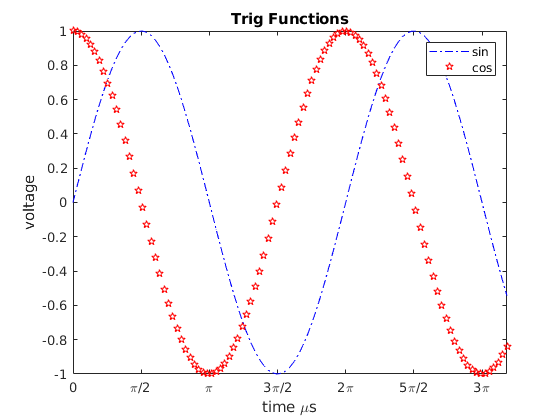

% Here we are going to get a bit fancy and change up some stuff. 
figure;

plot(t,d1,'b-.',t,d2,'rp') % We are changing up the line pattern and color
title('Trig Functions')
xlabel('time \mus') % \mus is a special symbol. Other examples include: \beta, \pi, \leq, \infty 
ylabel('voltage')
legend('sin','cos')
xticks(0:pi/2:10)
xticklabels({'0','\pi/2','\pi','3\pi/2','2\pi', '5\pi/2','3\pi'})

# SubPlots

Subplots exist for stylistic purposes. Let's say you have a signal and you want to plot the magnitude and phase of the signal. It would make more sense if the magnitude and phase plots exist in the same figure. There are several examples fo subplot below to explain how it works. Note that linear indexing of plots is different from normal linear indexing. 

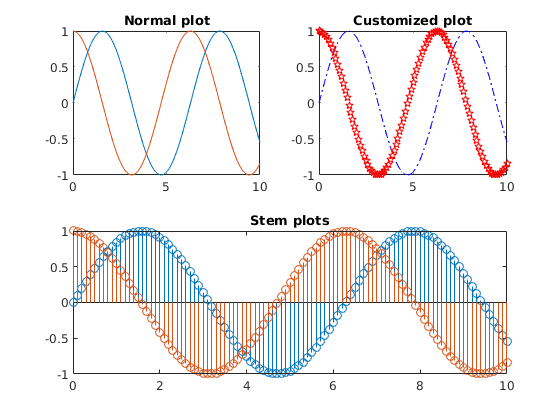

figure;
subplot(2,2,1)
plot(t,d1)
hold on;
plot(t,d2)
title('Normal plot')

subplot(2,2,2)
plot(t,d1,'b-.',t,d2,'rp')
title('Customized plot')

%% Stem plots
% stem plots are particularly useful when you are representing digital
% signals, hence it is good to learn them too!
subplot(2,2,[3 4])
stem(t,d1)
hold on;
stem(t,d2)
title('Stem plots')

# 3D and surface plots

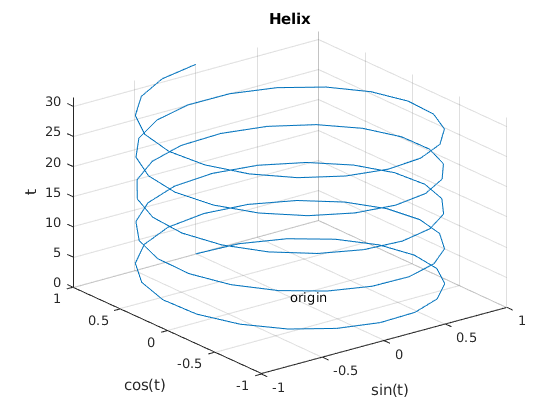

%% 3D and surface plots

% 3D plotting: The helix
t = linspace(0,10*pi);
figure;
plot3(sin(t),cos(t),t)
xlabel('sin(t)'),ylabel('cos(t)'),zlabel('t')
text(0,0,0,'origin')
grid on;
title('Helix')

# Tables

Tables are a great way to clearly display ones results. Conveniently, they are also very simple to use in MATLAB:

Schools = {'Architecture'; 'Engineering'; 'Art'};
Student_Count = [250; 250; 500];
t = table(Schools, Student_Count)

t = 3×2 table
       Schools        Student_Count
    ______________    _____________

    'Architecture'         250     
    'Engineering'          250     
    'Art'                  500     


# Functions

In MATLAB, there are 2 types of functions: anonymous functions and inline function. Writing functions is very important in MATLAB. Namely, if you have 10 lines of code that is going to be applied 1000 times with different variables names, you shouldn't have to write 10,000 lines of code!

**NOTE: **Functions can return one or more values.

# Anonymous Function

Anonymous functions do not need a separate file and can only consist of one expression. 

s = @(x) sin(1./x);
y = s(pi);
y_range = s(0:0.01:2*pi);

# Normal functions

Normally, functions are declared in another file, and we can **only use the function that is the NAME** of the file. Note that the local functions declared in myFunction.m cannot be used. (Go to lesson3_fn_demo.m to try it out!). Local functions to a file have to appear at the end of the file, after all the other code.

# Control Sequence - For loops

Similar to other languages, MATLAB has *if*, *while *and *for *control sequences. For loops are one of the commonly used control sequences in MATLAB.

n = 1000;
D = zeros(1000);    % This is called pre-allocation
D(1) = 1;
D(2) = 2;
tic
for i = 3:n
    D(i) = D(i-1)+D(i-2);
end
toc

Elapsed time is 0.006574 seconds.


## BE CAREFUL!

For loops are relatively inefficient operations in MATLAB - Do not use them unless it is completely necessary. Instead, try using VECTORATION, the action of using vectors to perform operations.

 A = rand(2000, 2000);
 % Nested loops approach.
 tic;
 count = 0;
 for i = 1:size(A,1)
    for j = 1:size(A,2)
        if A(i,j) > 0.8
           count = count + 1;
        end
    end
 end
 toc

Elapsed time is 9.740108 seconds.


 
 % Vector approach.
 tic;
 count = sum(A(:) > 0.8) ;
 toc

Elapsed time is 0.007516 seconds.


# Lab : Matrix Wrap Around

1. **Find the Peak:** Create a matrix with magic(5) and find the maximum of each row. Afterwards, set all numbers, except for the peak, to be zero. A hint would be to use *help max* to find out how to take the maximum of each row.

% WRITEME: Find the Peak
% STEP 1 : Create a magic matrix of size 5 x 5, store it in A
% STEP 2 : Create a column vector b, which stores the max of each row in A
% STEP 3 : Use the built-in find function, find the index at which A is equal to b, and store it as c
% STEP 4 : Create another matrix of size 5 x 5, initialize all elements to 0 with built-in zeros function, store it in C
% STEP 5 : Set the elements in C where its index in A gives you the max to be b

2. **Matrix Wrap Around:** Write a function which given a vector of distinct points $xVec=\text{ }\left\lbrack x_1 ,x_{2\text{ }} ,\ldotp \ldotp \ldotp ,x_N \right\rbrack$and a point $x$, finds the index $i^\ast $ such that $x_{i^\ast  } \le x$ and$x_{\left(i^\ast  +1\right)} >x$. You may assumed that the points are ordered and distinct, $x_i <x_{i+1} ,1\le i\le N-1$, but you should not assume that the points are equidistantly spaced. You may also assume that $x_1 \le x\le x_n$. You can do either anonymous or general function. Hint: Use the built-in function* find *and *max*.

Save the function in the file *findPivot.m*, and run your function for two cases: $x=\frac{1}{\sqrt{2}}$ and $xVec=0\ldotp 01\ast \left\lbrack 0:100\right\rbrack$; $x=0\ldotp 5$ and $xVec=sort\left(rand\left(1,100\right)\right)$

% WRITEME: Matrix Wrap Around : For anonymous functions